Implementation of Paper  Titled - "**RIS-Aided Wireless Communications: Prototyping, Adaptive Beamforming, and Indoor/Outdoor Field Trials**" -  Author : Xilong Pei

We are implementing a greedy algorithm to decide the optimum  Array Phase Response of IRS, with the following assumptions - 

- phase shifts of the IRS can take binary values of either +pi/2 or -pi/2. 

-  Only 1 Tx and 1 Rx antennas are there. Or only one dominant eigen mode exists btwn AP - RIS as well as RIS-UE

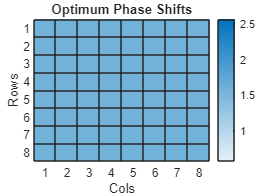

close all; clearvars; clc;
M = 8; % no of rows
N = 8; % no of cols
nrefl = M*N;
del_time = 1;

% Define fading coeffs for AP-RIS and RIS-UE channels. We assume
% independent channel.
H_ap2ris = (1/sqrt(2))*(randn(nrefl,1) +1i*randn(nrefl,1)); % channel from ap to ris;
H_ris2ue = (1/sqrt(2))*(randn(nrefl,1) +1i*randn(nrefl,1)); % channel from ris to ue;
apr = 1i*ones(nrefl,1); % RIS Reflector Array Phase Response. Set initial values.
plotapr(apr,M,N); pause(del_time);

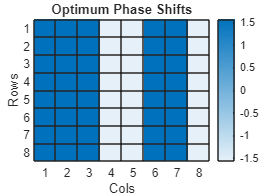


% Only two responses are possible for the reflectors -> pi/2 or -pi/2 phase
% rotation

% We assume only one tx and one rx antenna at AP and UE( or one dominant
% eigen mode)
% Assume infinite coherence time.

nbits = 1e3;
sym = 2*randi([0,1],1,nbits) -1;
chan_out = zeros(size(sym));

H = (1/nrefl)*H_ap2ris .* apr .*H_ris2ue ; % Total channel response
for i = 1: length(sym)
    chan_out(i) = sum(sym(i)*H);
end
rsrp_prev = mean(abs(chan_out).^2); % This value has to be maximised using Greedy Algorithm
rsrp_max = rsrp_prev;
for j = 1: M % row wise raster

    apr_new = update_apr(apr,j,'rowwise',M,N);
    H = (1/nrefl)*H_ap2ris .* apr_new .*H_ris2ue ; % Total channel response
    for i = 1: length(sym)
        chan_out(i) = sum(sym(i)*H);
    end
    rsrp_curr = mean(abs(chan_out).^2); % This value has to be maximised using Greedy Algorithm
    
    if(rsrp_curr > rsrp_prev)
        apr = apr_new;
        rsrp_max = rsrp_curr;
    else
        rsrp_max = rsrp_prev;
    end
    plotapr(apr,M,N); pause(del_time);
end

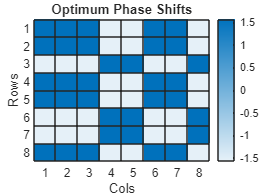


rsrp_prev = rsrp_max;
for j = 1: N % col wise raster

    apr_new = update_apr(apr,j,'colwise',M,N );
    H = (1/nrefl)*H_ap2ris .* apr_new .*H_ris2ue ; % Total channel response
    for i = 1: length(sym)
        chan_out(i) = sum(sym(i)*H);
    end
    rsrp_curr = mean(abs(chan_out).^2); % This value has to be maximised using Greedy Algorithm
    
    if(rsrp_curr > rsrp_prev)
        apr = apr_new;
        rsrp_max = rsrp_curr;
    else
        rsrp_max = rsrp_prev;
    end
    plotapr(apr,M,N);drawnow; pause(del_time);
end

function [apr_new] = update_apr(apr,j,str,M,N)

    apr_new = reshape(apr,[M,N]);
    if(strcmp(str,'rowwise'))
        apr_new(:,j) = -apr_new(:,j);
    end

    if(strcmp(str,'colwise'))
        apr_new(j,:) = -apr_new(j,:);
    end
    apr_new = apr_new(:);

end

function plotapr(apr,M,N)

    cdata = (pi/2)*sign(imag(reshape(apr,[M,N])));
    heatmap(cdata,'Title','Optimum Phase Shifts','XLabel','Cols','YLabel','Rows');

end